clear
close all
clc
addpath 'C:\GitHub\CVUT-MatLab\Resources'
tic

## Sections

sections.A  = [1];
sections.Iy = [0.5];
sections.Iz = [1];
sections.Ix = [2];
sections.E  = [100];
sections.v  = [0.5];

ndisc = 2;


## Nodes

nodes.x = [0;0];                            % x coordinates of nodes
nodes.y = [0;20];                              % y coordinates of nodes
nodes.z = [0;0];
nnodes = numel(nodes.x); 

## Supports

kinematic.x.nodes = [1];              % node indices with restricted x-direction displacements
kinematic.y.nodes = [1];              % node indices with restricted y-direction displacements
kinematic.z.nodes = [1];              % node indices with restricted z-direction displacements
kinematic.rx.nodes = [1];                    % node indices with restricted x-direction displacements
kinematic.ry.nodes = [1];                   % node indices with restricted y-direction displacements
kinematic.rz.nodes = [1];                    % node indices with restricted z-direction displacements

nodes.dofs = true(nnodes,6);                % no kinematic boundary conditions
nodes.dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction
nodes.dofs(kinematic.rx.nodes,4) = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.ry.nodes,5) = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.rz.nodes,6) = false;    % mark prevented movement in z-direction

## Beams

modulNodes1 = [1];   % elements starting nodes
beams.nodesHead = modulNodes1;
modulNodes2 = [2];   % elements ending nodes
beams.nodesEnd = modulNodes2;
nr = numel(beams.nodesHead);

### Beams sections

beams.disc      = ones(nr,1)*ndisc;
modulElemGroup = [1];
beams.sections = modulElemGroup;
plot3([nodes.x(beams.nodesHead) nodes.x(beams.nodesEnd)]', ...
     [nodes.y(beams.nodesHead) nodes.y(beams.nodesEnd)]', ...
     [nodes.z(beams.nodesHead) nodes.z(beams.nodesEnd)]', ...
     'k','LineWidth',1);
hold on;
scatter3(nodes.x, nodes.y, nodes.z, 'black', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
zlim([min(nodes.z)-1,max(nodes.z)+1]);  % to avoid tight limits
grid on
% view([90 0])


## Loads

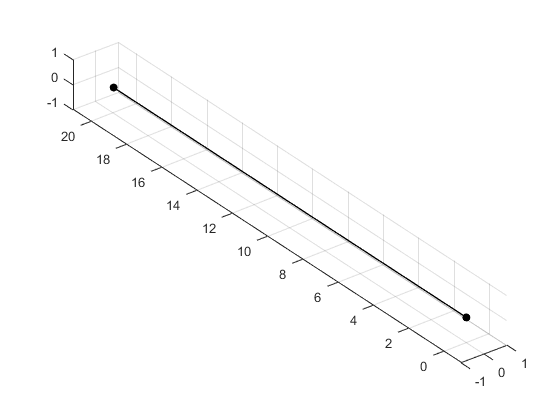

% loads.x.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with x-direction forces
% loads.x.value = [-10000;-10000;-10000;-10000];             % magnitude of the x-direction forces
% loads.y.nodes = reshape((repmat([1,2], nbricks, 1) + (1:nbricks)'*8).',1,[])';          % node indices with y-direction forces
% loads.y.value = ones(nbricks*2,1)*0.25;          % magnitude of the y-direction forces 
% loads.z.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with z-direction forces
% loads.z.value = [-10000;-10000;-10000;-10000];
loads.y.nodes = [2];             % node indices with x-direction forces
loads.y.value = [-1];             % magnitude of the x-direction forces
loads.x.nodes = [2];             % node indices with y-direction forces
loads.x.value = [-1];             % magnitude of the y-direction forces 
loads.z.nodes = [2];             % node indices with y-direction forces
loads.z.value = [-1];             % magnitude of the y-direction forces 

loads.rx.nodes = [2];          % node indices with x-direction forces
loads.rx.value = [-1];          % magnitude of the x-direction forces
loads.ry.nodes = [2];          % node indices with y-direction forces
loads.ry.value = [-1];          % magnitude of the y-direction forces 
loads.rz.nodes = [2];          % node indices with z-direction forces
loads.rz.value = [-1]; 
% scatter3(nodes.x(loads.x.nodes), nodes.y(loads.x.nodes), nodes.z(loads.x.nodes), 'red', 'filled', 'o');
% scatter3(nodes.x(loads.x.nodes)-1, nodes.y(loads.x.nodes), nodes.z(loads.x.nodes), 'green', 'filled', 'o');
hold off;

## Force vector

forceVector = sparse([loads.x.nodes*6-5; loads.y.nodes*6-4; loads.z.nodes*6-3;loads.rx.nodes*3-2; loads.ry.nodes*3-1; loads.rz.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value;loads.rx.value; loads.ry.value; loads.rz.value], ...
                     nnodes*6, 1);
f = forceVector(reshape(reshape(nodes.dofs.',[],1).', 1, [])');
% f = full(f)

## FEM

nodes.ndofs = sum(sum(nodes.dofs));
nodes.nnodes    = nnodes;

beams.nbeams  = nr;
beams.vertex = beamVertexFn(beams,nodes);
beams.codeNumbers = codeNumbersFn(beams,nodes);
beams.XY = XYtoBeamsFn(beams);

elements = discretizationBeamsFn(beams,nodes);
elements.XY = XYtoElementFn(beams);
elements.sections = sectionToElementFn(sections,beams);
elements.ndofs = max(max(elements.codeNumbers));



%------------------------------------------------------------------------
%   Linear analysis
%------------------------------------------------------------------------
endForces.global = sparse(elements.ndofs,1);
endForces.global(1:max(max(beams.codeNumbers))) = f;

transformationMatrix = transformationMatrixFn(elements);

stiffnesMatrix = stiffnessMatrixFn(elements,transformationMatrix);

[endForces.local, displ] = EndForcesFn(stiffnesMatrix,endForces,transformationMatrix,elements);
%------------------------------------------------------------------------
%   Non-linear analysis
%------------------------------------------------------------------------
% geometricMatrix = geometricMatrixFnV2(elements,transformationMatrix,endForces);
% geometricMatrix = geometricMatrixFn(elements,transformationMatrix,endForces);

[geometricMatrix.local,geometricMatrix.global] = geometricMoofemFn(elements.sections.A,...
         elements.sections.Ix,transformationMatrix.matrices,transformationMatrix.lengths,endForces.local,elements.ndofs,...
         elements.nelement,elements.codeNumbers,12);

volume = sum(elements.sections.A .* transformationMatrix.lengths)

volume = 20

% 
Results = criticalLoadFn(stiffnesMatrix,geometricMatrix);
% 
[sortedValues,sortedVectors]= sortValuesVectorFn(Results.values,Results.vectors);

% SortedResults = criticalLoadFnV2(stiffnesMatrix,geometricMatrix);

disp('1. kritické břemeno')

1. kritické břemeno


disp([num2str(sortedValues(1)),' N'])

0.30858 N


disp('2. kritické břemeno')

2. kritické břemeno


disp([num2str(sortedValues(2)),' N'])

0.61717 N


disp('3. kritické břemeno')

3. kritické břemeno


disp([num2str(sortedValues(3)),' N'])

2.8683 N


% disp('4. kritické břemeno')
% disp([num2str(sortedValues(4)),' N'])
% disp('5. kritické břemeno')
% disp([num2str(sortedValues(5)),' N'])
% disp('6. kritické břemeno')
% disp([num2str(sortedValues(6)),' N'])
% disp('7. kritické břemeno')
% disp([num2str(sortedValues(7)),' N'])
% disp('8. kritické břemeno')
% disp([num2str(sortedValues(8)),' N'])
% disp('9. kritické břemeno')
% disp([num2str(sortedValues(9)),' N'])
% disp('10. kritické břemeno')
% disp([num2str(sortedValues(10)),' N'])
toc

Elapsed time is 0.253078 seconds.



for i = 1:nr
    idR = 1:12;
    idC = (i-1)*ndisc + 1 : i*ndisc;
    
    % Vytvoření podmatice
    endForces.beams{i} = endForces.local(idR, idC);
    N(1,i)=endForces.beams{i}(7,1);
    N(2,i)=endForces.beams{i}(8,1);
    N(3,i)=endForces.beams{i}(9,1);
    displ.beams{i} = displ.local(idR, idC);
end
N = N'/1000;
for neig=1:6
    nf = size(f,1);
    supports=reshape(sortedVectors(1:12,neig),3,4)';
    free=reshape(sortedVectors(13:nf,neig), 6, [])';
    nfree = size(free);
    
    koko(1:4,1:3) = 0;
    koko(1:4,4:6) = supports;
    koko(5:nfree(1)+4,1:nfree(2))= free;
    norm = max(max(abs(koko)));
    eigVectors{neig} = koko/norm;
end